%%  Import predictions with different resolution
load('./input_data/fndds4RF.mat')
load('./input_data/predictions_diffresolution.mat')
load('./input_data/db5foldsSMOTE.mat')
% for plots
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultAxesFontSize',15)

%% which db to use when you check NOVA classification
dn=unique(NOVAclass(:, {'dr12ifdcd', 'fc_or_sr'}));
mainfooddesc5.whichdb=dn.fc_or_sr;

disp('How many f foods (FNDDS)')

How many f foods (FNDDS)


disp(sum(mainfooddesc5.whichdb=='f'))

        2484



disp('%')

%


disp(sum(mainfooddesc5.whichdb=='f')/height(mainfooddesc5))

    0.3425




t=mainfooddesc5(mainfooddesc5.whichdb=='f',:);
disp('Manual classes as f')

Manual classes as f


disp('Class 1')

Class 1


disp(sum(t.novaclass==1))

   228



disp('%')

%


disp(sum(t.novaclass==1)/height(t)*100)

    9.1787





disp('Class 2')

Class 2


disp(sum(t.novaclass==2))

    50



disp('%')

%


disp(sum(t.novaclass==2)/height(t)*100)

    2.0129




disp('Class 3')

Class 3


disp(sum(t.novaclass==3))

   333



disp('%')

%


disp(sum(t.novaclass==3)/height(t)*100)

   13.4058





disp('Class 4')

Class 4


disp(sum(t.novaclass==4))

        1873



disp('%')

%


disp(sum(t.novaclass==4)/height(t)*100)

   75.4026



%% choose the db
dbtableall=RFFNDDScleanedwithsaltadditionallabPREDICTION995foldsSMOTE;
minensemble=false;

if minensemble
    col2sel={'Food_code', 'Main_food_description', 'catname', 'novaclass', 'macroclass'};
    dbtable=dbtableall(:, col2sel);
    dbtable.class=dbtableall.min_class;
    dbtable.p1=dbtableall.p1_minFPS;
    dbtable.p2=dbtableall.p2_minFPS;
    dbtable.p3=dbtableall.p3_minFPS;
    dbtable.p4=dbtableall.p4_minFPS;
    dbtable.FPS=dbtableall.min_FPS;
else  
    col2sel={'Food_code', 'Main_food_description', 'catname', 'novaclass', 'macroclass', 'class', 'p1','p2', 'p3','p4', 'FPS'};
    dbtable=dbtableall(:, col2sel);
end

db=dbtable{:, {'p1','p2', 'p3','p4'}};

%% summary of our classification
% remove the addition of salt
dbstat=dbtable(2:end,:);
disp('Class 1')

Class 1


disp(sum(dbstat.class==0))

   536



disp('%')

%


disp(sum(dbstat.class==0)/height(dbstat)*100)

    7.3900





disp('Class 2')

Class 2


disp(sum(dbstat.class==1))

    65



disp('%')

%


disp(sum(dbstat.class==1)/height(dbstat)*100)

    0.8962




disp('Class 3')

Class 3


disp(sum(dbstat.class==2))

        1332



disp('%')

%


disp(sum(dbstat.class==2)/height(dbstat)*100)

   18.3648





disp('Class 4')

Class 4


disp(sum(dbstat.class==3))

        5320



disp('%')

%


disp(sum(dbstat.class==3)/height(dbstat)*100)

   73.3490



%% colormap as a container (NOVA classes)
mainfooddesc5.novaclass(mainfooddesc5.whichdb=='s')=12;
% * *

keySet={0,12,1,2,3,4};
valueSet={[102, 102, 102]/255,...
    [102, 102, 102]/255,...
    [0.4, 0.7607843137254902, 0.6470588235294118],...
    [0.9882352941176471, 0.5529411764705883, 0.3843137254901961],...
    [0.5529411764705883, 0.6274509803921569, 0.796078431372549],...
    [0.9058823529411765, 0.5411764705882353, 0.7647058823529411]};
colormapNOVA=containers.Map(keySet, valueSet);

% pca
[coeff,score,latent] = pca(db);
centerp=mean(db);

yeslabel=false;

% NOVA colors (our corrections)
cNOVA=zeros(size(db,1),3);
for ind=1:size(db,1)
    cNOVA(ind,:)=colormapNOVA(dbtable.novaclass(ind));

end
% NOVA colors (originals)...according to what they have classified
cNOVA2=zeros(size(mainfooddesc5,1),3);
for ind=1:size(mainfooddesc5,1)
    cNOVA2(ind,:)=colormapNOVA(mainfooddesc5.novaclass(ind));

end

% add salt to cNOVA2
cNOVA2=[cNOVA(1,:);cNOVA2];
classesNOVA2=[2;mainfooddesc5.novaclass];

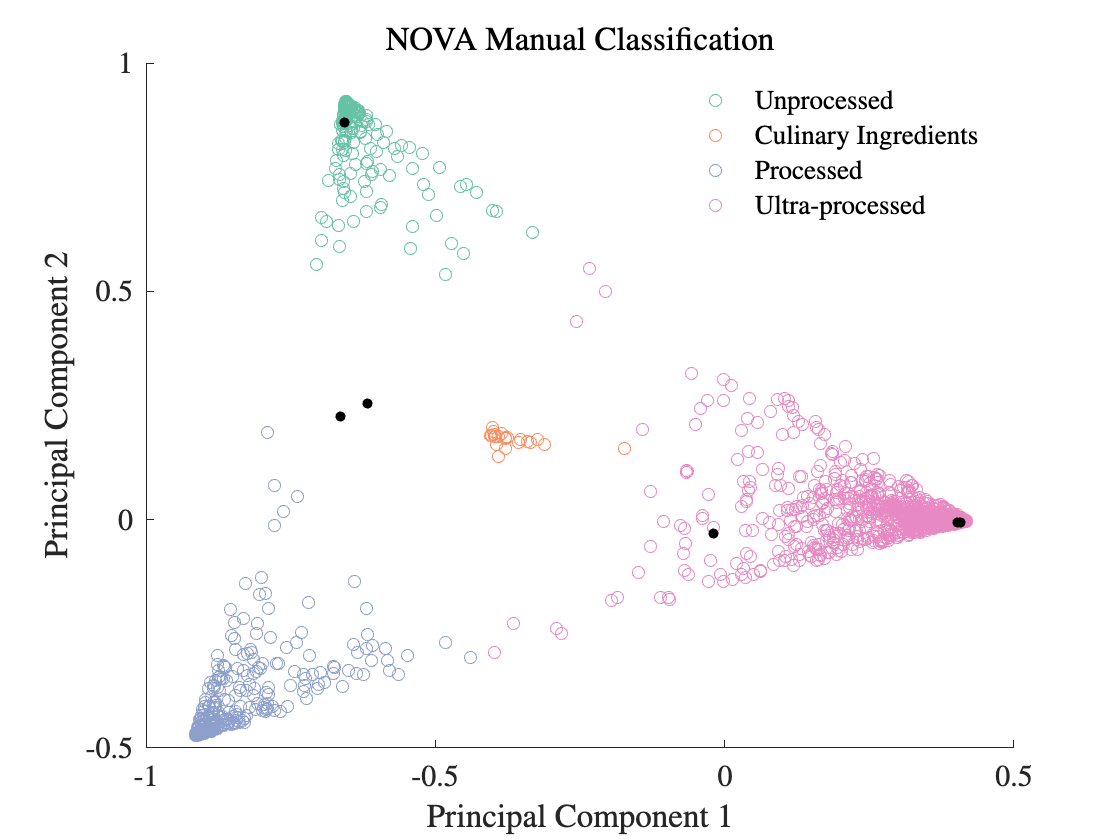

%% Figure 2

labelfoodlist={'Onions, mature, raw',...
    'Onions, mature, cooked, from fresh, fat not added in cooking',...
    'Onions, mature, cooked, from frozen, fat not added in cooking', ...
    'Onions, mature, cooked, from fresh, NS as to fat added in cooking',...
    'Onions, mature, cooked or sauteed, from fresh, fat added in cooking',...
    'Onion rings, from fresh, batter-dipped, baked or fried',...
    'Onion rings, from frozen, batter-dipped, baked or fried'};


keySetfull={1,2,3,4};
keySetempty={0,12};
keySetemptysymbols={'o','s'};

% manual space
figure,
for ind=1:length(keySetfull)
    filter=(classesNOVA2==keySetfull{ind});
    if(sum(filter)>0)
        s=scatter(score(filter,1), score(filter,2),[],colormapNOVA(keySetfull{ind}), 'o');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

xlabel('Principal Component 1')
ylabel('Principal Component 2')
ll=legend('Unprocessed', 'Culinary Ingredients', 'Processed', 'Ultra-processed');
ll.EdgeColor='none';
title('NOVA Manual Classification')
hold on
for ind=1:length(labelfoodlist)
    coord=score(strcmpi(labelfoodlist{ind}, dbtable.Main_food_description), :);
    p=plot(coord(1), coord(2), 'k.');
    p.MarkerSize=15;
    p.HandleVisibility='off';
    if(yeslabel)
    text(coord(1), coord(2),labelfoodlist{ind})
    end
    hold on
end

%% Processing Line
drawArrow2c = @(xc,yc,x,y,c) quiver(xc,yc,x,y, 'LineWidth',2, 'Color',c, 'AutoScale' ,'off'); 
labelfoodlist={'Onions, mature, raw',...
    'Onions, mature, cooked, from fresh, fat not added in cooking',...
    'Onions, mature, cooked, from frozen, fat not added in cooking', ...
    'Onions, mature, cooked, from fresh, NS as to fat added in cooking',...
    'Onions, mature, cooked or sauteed, from fresh, fat added in cooking',...
    'Onion rings, from fresh, batter-dipped, baked or fried',...
    'Onion rings, from frozen, batter-dipped, baked or fried'};


figure,
for ind=1:length(keySet)
    filter=((dbtable.class+1)==keySet{ind});
    if(sum(filter)>0)
        s=scatter(score(filter,1), score(filter,2),[],colormapNOVA(keySet{ind}), 'filled');
        s.MarkerFaceAlpha=0.5;
        hold on
    end
end

% s=scatter(score(:,1), score(:,2),[],cpredicted, 'filled');
% s.MarkerFaceAlpha=0.5;
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('Random Forest Classification')

hold on

e1=[1,0,0,0]-centerp;
e4=[0,0,0,1]-centerp;
v1proj=[dot(e1', coeff(:,1)), dot(e1', coeff(:,2))];
v4proj=[dot(e4', coeff(:,1)),  dot(e4', coeff(:,2))];
drawArrow2c(v1proj(1),v1proj(2),v4proj(1)-v1proj(1),v4proj(2)-v1proj(2),[152,0,67]/255)

hold on 
for ind=1:length(labelfoodlist)
    disp('%%%%%%%%%%%%')
    disp(labelfoodlist{ind})
    boolfood=(strcmpi(labelfoodlist{ind}, dbtable.Main_food_description));
    coord=score(boolfood, :);
    p=plot(coord(1), coord(2), 'k.');
    p.MarkerSize=15;
    p.HandleVisibility='off';
    if(yeslabel)
        text(coord(1), coord(2),labelfoodlist{ind})
    end
    disp("PCA coordinates")
    disp([coord(1), coord(2)])
    disp(dbtable(boolfood, {'p1','p2', 'p3','p4'}))
    hold on
    
    portg=[(1+db(boolfood,1)-db(boolfood,4))/2,0,0,(1-db(boolfood,1)+db(boolfood,4))/2];
    portgc=portg-centerp;
    portgproj=[dot(portgc', coeff(:,1)), dot(portgc', coeff(:,2))];
    hold on
    p1=plot([coord(1),portgproj(1)], [coord(2), portgproj(2)], 'k-');
    p1.HandleVisibility='off';  
    p1.LineWidth=1.5;
    p1.LineStyle='--';
    
    disp('Check orthgonal')
    disp(dot(db(boolfood,:)-portg, e4-e1))

end

%%%%%%%%%%%%


Onions, mature, raw


PCA coordinates


   -0.6566    0.8703



      p1          p2           p3          p4    
    ______    __________    ________    _________

    0.9651    0.00022222    0.028889    0.0057926



Check orthgonal


   6.5919e-17



%%%%%%%%%%%%


Onions, mature, cooked, from fresh, fat not added in cooking


PCA coordinates


   -0.6647    0.2260



      p1           p2          p3        p4   
    _______    __________    ______    _______

    0.47078    0.00044444    0.4329    0.09588



Check orthgonal


   5.5511e-17



%%%%%%%%%%%%


Onions, mature, cooked, from frozen, fat not added in cooking


PCA coordinates


   -0.6164    0.2534



      p1        p2        p3         p4   
    _______    _____    _______    _______

    0.47859    0.001    0.39002    0.13039



Check orthgonal


   8.3267e-17



%%%%%%%%%%%%


Onions, mature, cooked, from fresh, NS as to fat added in cooking


PCA coordinates


   -0.0190   -0.0311



       p1          p2          p3         p4   
    ________    _________    _______    _______

    0.096278    0.0027778    0.24883    0.65211



Check orthgonal


   2.7756e-17



%%%%%%%%%%%%


Onions, mature, cooked or sauteed, from fresh, fat added in cooking


PCA coordinates


   -0.0190   -0.0311



       p1          p2          p3         p4   
    ________    _________    _______    _______

    0.096278    0.0027778    0.24883    0.65211



Check orthgonal


   2.7756e-17



%%%%%%%%%%%%


Onion rings, from fresh, batter-dipped, baked or fried


PCA coordinates


    0.4028   -0.0059



     p1          p2           p3         p4   
    _____    __________    ________    _______

    0.002    0.00011111    0.010111    0.98778



Check orthgonal


   1.7347e-18



%%%%%%%%%%%%


Onion rings, from frozen, batter-dipped, baked or fried


PCA coordinates


    0.4083   -0.0051



       p1            p2           p3          p4   
    _________    __________    _________    _______

    0.0011111    0.00011111    0.0066667    0.99211



Check orthgonal


  -4.8572e-17



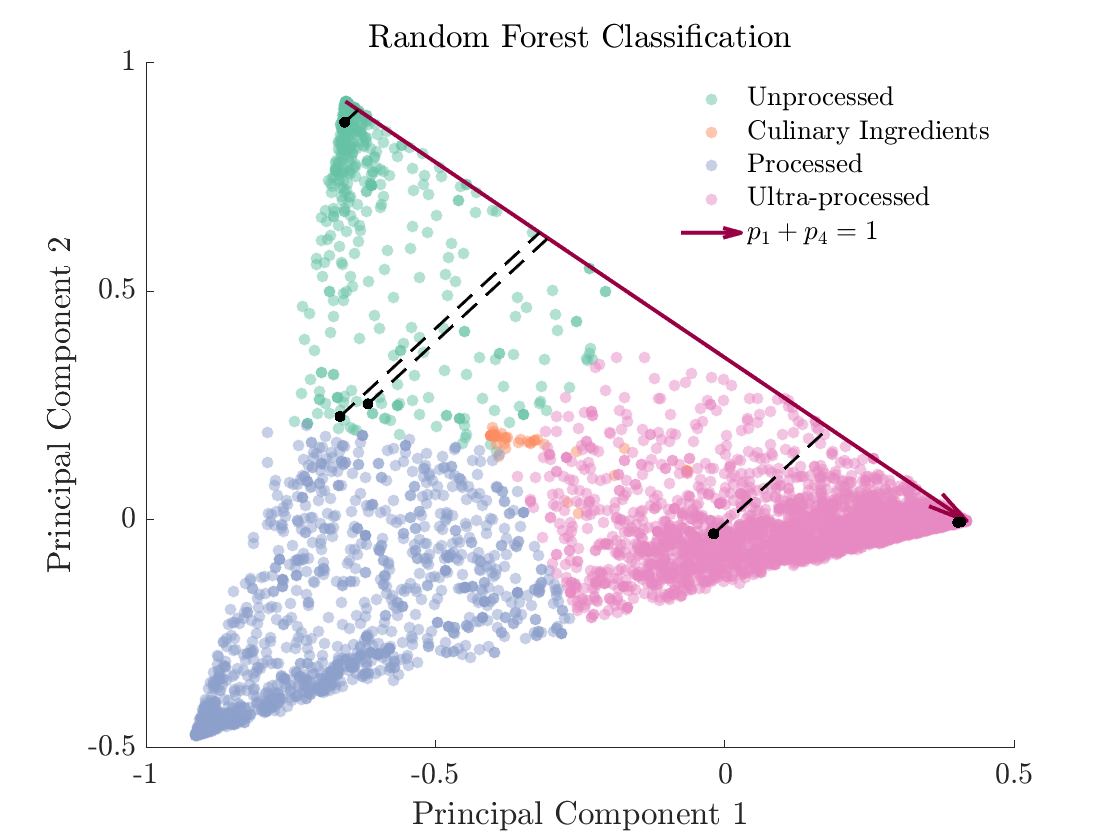



ll=legend('Unprocessed', 'Culinary Ingredients', 'Processed', 'Ultra-processed', '$p_1+p_4=1$');
ll.EdgeColor='none';

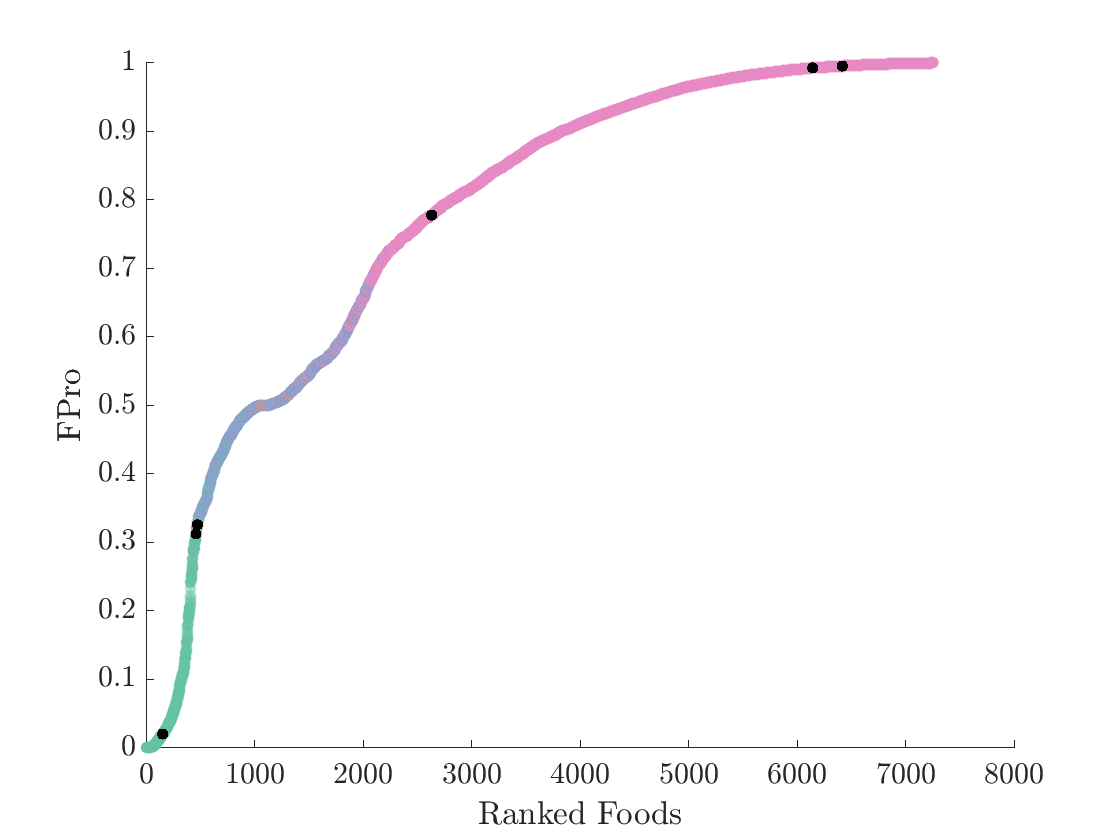

%%%%%%%%%%%%


Onions, mature, raw


Probabilities


    0.9651    0.0002    0.0289    0.0058



Score


    0.0203



%%%%%%%%%%%%


Onions, mature, cooked, from fresh, fat not added in cooking


Probabilities


    0.4708    0.0004    0.4329    0.0959



Score


    0.3126



%%%%%%%%%%%%


Onions, mature, cooked, from frozen, fat not added in cooking


Probabilities


    0.4786    0.0010    0.3900    0.1304



Score


    0.3259



%%%%%%%%%%%%


Onions, mature, cooked, from fresh, NS as to fat added in cooking


Probabilities


    0.0963    0.0028    0.2488    0.6521



Score


    0.7779



%%%%%%%%%%%%


Onions, mature, cooked or sauteed, from fresh, fat added in cooking


Probabilities


    0.0963    0.0028    0.2488    0.6521



Score


    0.7779



%%%%%%%%%%%%


Onion rings, from fresh, batter-dipped, baked or fried


Probabilities


    0.0020    0.0001    0.0101    0.9878



Score


    0.9929



%%%%%%%%%%%%


Onion rings, from frozen, batter-dipped, baked or fried


Probabilities


    0.0011    0.0001    0.0067    0.9921



Score


    0.9955



%% projection --> Processing Score 

colormapEIG=zeros(size(db,1),3);
for ind=1:size(db,1)
    colormapEIG(ind,:)=colormapNOVA(dbtable.class(ind)+1);
end

[sortedproj1, indsp]=sort(dbtable.FPS);


figure,
s=scatter(1:length(sortedproj1),sortedproj1,[],colormapEIG(indsp,:), 'filled');
s.MarkerFaceAlpha=0.5;
xlabel('Ranked Foods')
ylabel('FPro')

yeslabel=false;
hold on 
labelfoodlist={'Onions, mature, raw',...
    'Onions, mature, cooked, from fresh, fat not added in cooking',...
    'Onions, mature, cooked, from frozen, fat not added in cooking', ...
    'Onions, mature, cooked, from fresh, NS as to fat added in cooking',...
    'Onions, mature, cooked or sauteed, from fresh, fat added in cooking',...
    'Onion rings, from fresh, batter-dipped, baked or fried',...
    'Onion rings, from frozen, batter-dipped, baked or fried'};
for ind=1:length(labelfoodlist)
    disp('%%%%%%%%%%%%')
    disp(labelfoodlist{ind})
    coord=dbtable.FPS(strcmpi(labelfoodlist{ind}, dbtable.Main_food_description));
    p=plot(min(find(sortedproj1==coord)), coord, 'k.');
    p.MarkerSize=15;
    p.HandleVisibility='off';
    if(yeslabel)
    text(min(find(sortedproj1==coord)), coord,labelfoodlist{ind}, 'Fontsize', 15)
    end
    %disp([min(find(sortedproj1==coord)), coord])
    
    disp('Probabilities')
    disp(db(strcmpi(labelfoodlist{ind}, dbtable.Main_food_description), :))
    disp('Score')
    disp(coord)
    
    hold on
end